# Roordalab Custom Shack-Hartmann Sensor

Data-reduction pipeline for processing spot-field images

clearvars
close all

A raw Shack-Hartmann spot field image of just a single megapixel contains over a million numbers. The process of reducing this massive amount of data into either a wavefront "surface" sampled over a grid of a few hundred points or a set of polynomial coefficients for a model representation is known as *data reduction*.

measurementFileName = "R25M0006g.tif";  

## Preprocessing 

If background image is available, alway subtract background.  Pixels outside of physical pupil defines detector noise. We assume the hardware is designed well enough that it's not possible for significant straylight to land on pixels beyond the max supported pupil size

Pupil Estimation

Adaptive threshold rough extraction of spot pixels from background noise pixel

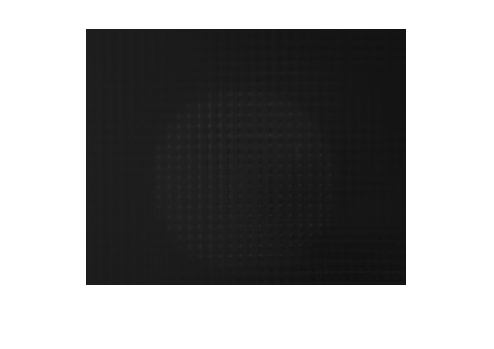

% load background and measurement images
bkgd = imread("background.tif");
meas = imread(measurementFileName);

I = uint8(meas - bkgd);
I = imresize(I, 0.25, "AntiAliasing", true);


imshow(I)



% create Shack-Hartmann sensor model
% model = Roorda(bkgd);
% model.process(meas);
% model.show()

## Spot Sorting

Row and column reduction followed by peak analysis

## Centroiding

## Reconstruction

Wavefront slopes followed by regression

Determine the optimal threshold parameter(s) to isolate pupil in spot-field image

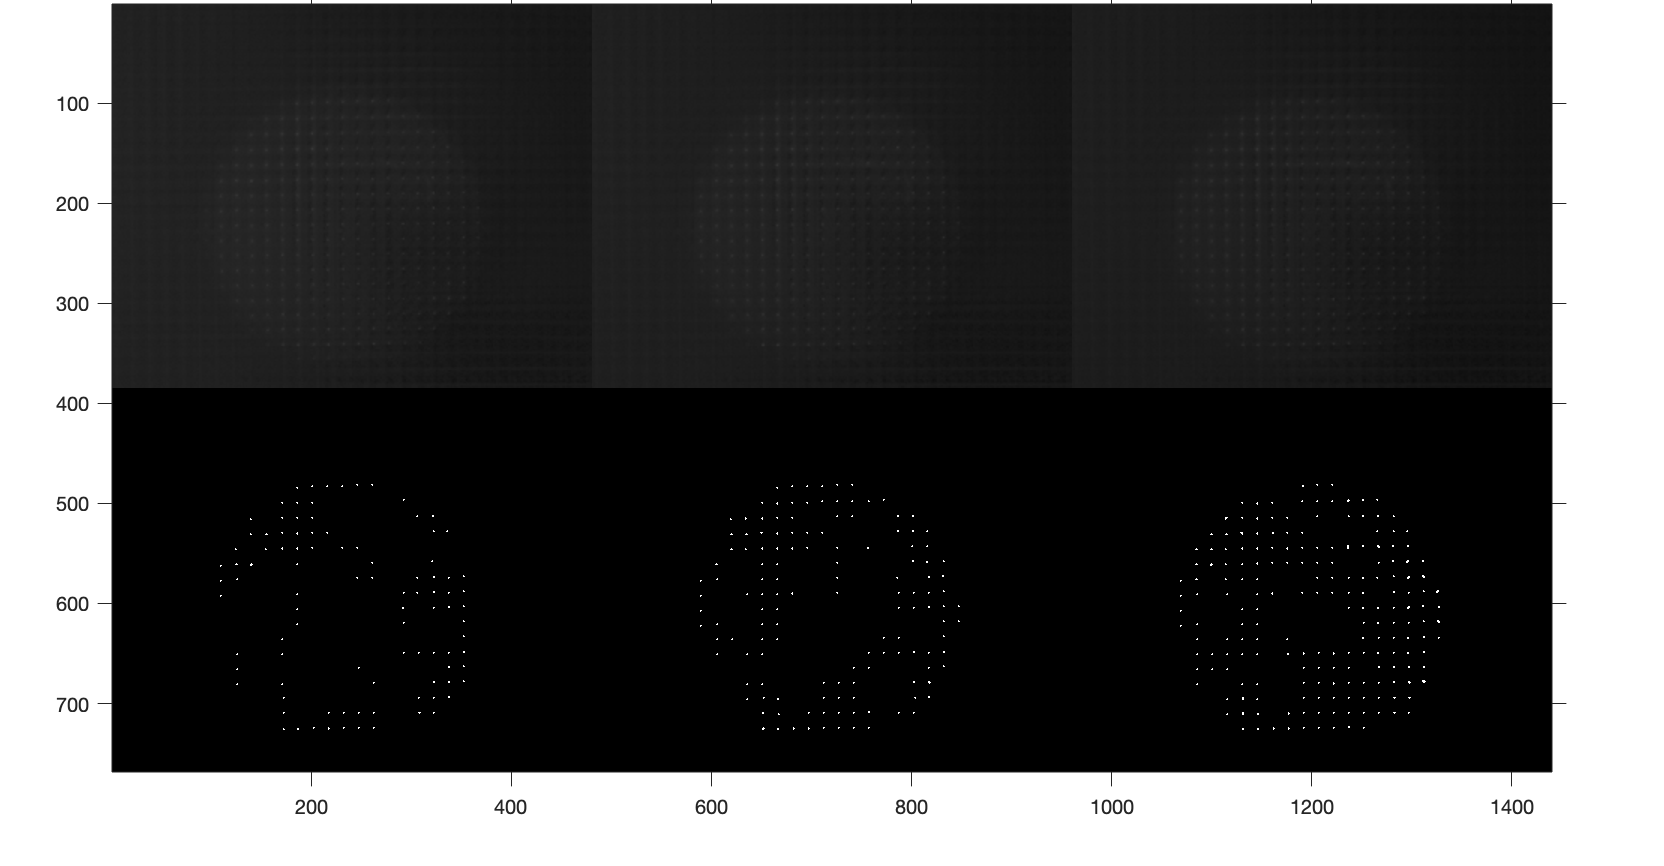

clearvars
close all
sensitivity = 0.3;  

% load images, subtract background, and resize
bkgd = imread("background.tif");
images = {imread("R25M0004g.tif"), imread("R25M0005g.tif"), imread("R25M0006g.tif")}';
binImages = cell(3,1);
for ind = 1:length(images)
    images{ind} = imresize(imsubtract(images{ind}, bkgd), 0.25, "AntiAliasing", true);
    binImages{ind} = imbinarize(images{ind}, "adaptive", "Sensitivity", sensitivity);
end
montage([images, binImages] , "Size", [2 length(images)])